# Kinematic analysis and trajectory generation of a customizable multi-flavor ice-cream dispensing robot

Authors:

- Kathia Coronado - *kcoronado@wpi.edu*

- Nithin Kumar - *nkumar2@wpi.edu*

- Keith Chester - *kchester@wpi.edu*

## Introduction

Robotics and automation can help the food industry by addressing labor shortage concerns, decreasing operational costs, and improving reliability of the final product. Furthermore, the COVID-19 pandemic has demonstrated the need for safe distribution of food and other supplies, and there has been significant research in the use of robotic automation to address this [1,2]. In particular, we will use the Soft Serve Ice Cream Robot from Connected Robotics as a template for analyzing a class of ice-cream dispensing robots. The novelty here is that the current state-of-the-art class of robot does not offer the customer any customization options that a human operator might indulge. Efforts presented in this paper will help bridge the gap between customer satisfaction and the use of robotics in the service industry. [3] presents an autonomous ice-cream serving robot that uses a KUKA-style manipulator to physically scoop ice-cream into a cup using a vision-based system and impedance control. Our approach differs in that the complexity of the system is minimized and yet offers a degree of customization. We will present an approach that takes in up to three customer flavor choices, generates a trajectory that avoids kinematic singularities and is within acceleration bounds, and dispenses the curated ice-cream within 60 seconds. 

Existing robot arm automation solutions that work within the food industry either require significant hardware investment or have to solve complicated grasping of food. For instance, in "Modeling & control of a meat-cutting robotic cell**” [xxx], **we see that the application of butchering meat by an automated system requires two six axis robotic arms and has to 3d scan the deformable body of meat as it is being cut. [4]  For some applications, a specialty end effector can simplify complicated handling and grasping tasks, such as in “Design of an Automated Handling System for Limp, Flexible Sheet Lasagna Pasta” [5]. Custom actuators, however, add complexity and cost. Despite these advances, robotic arms remain a novelty in the food industry, especially in fast food service markets. A robotic arm with limited pre-planned trajectories and a passive end effector can provide simpler and more cost effective applications in the food industry and could be a model for future advances in the market.

The main goal of this group assignment is to apply and explore the topics learned in the Foundation of Robotics course to a real life robotics system used in industry. Our objective for this group project is to analyze a KUKA-like ice cream serving robot with the ability to dispense upto three flavors into an ice cream cone. In order to accomplish this each group member will be responsible for some of the development tasks, see table 1 **[there is no table?]**. First the forward kinematics of the robot will be solved in order to obtain the position of the end-effector with respect to the base frame. After this, the symbolic Jacobian for the system will be calculated, this will relate the joint velocities to the end effector velocities. Using the jacobian, the system will be analyzed for singular configurations. A numerical inverse kinematic analysis will be conducted on the system in order to find the values of the joint velocities at the initial and final positions of the manipulator. The implicit Euler numerical inverse kinematics method will be used, as it has been shown that the solution tends to converge faster and the tracking error is smaller using this method [6]. After this the trajectory planning equations displayed in section 7.5 of the robot modeling and control textbook by spong et al. **[cite this with just a number]** will be used to solve for the desired path. The steps involved in this robot’s path are described in the steps below:

**Step 1:** Robot takes order at counter (home configuration)

- Example order: Vanilla, chocolate and mango

**Step 2:**  Robot goes to each of the dispenser in the order specified by the customer 

- Example path: Vanilla, chocolate and then to mango dispensing station 

**Step 3:** Robot returns to home with ice cream

**Step 4:** Repeat 

## Methods

Here we will describe the approach to model, simulate, and analyze the ice-cream dispensing robot. In this section, we will discuss the derivation of forward kinematics, construction of the Jacobian for singularity analysis, derive the algorithm for numerical inverse kinematics, and discuss our approach for trajectory planning.

### Forward Kinematics

Forward kinematics refers to the process of calculating the position and orientation of a robot’s end-effector (or any desired final frame) with respect to a base frame. This is useful in order to keep track of the robot’s end-effector given a set of input joint angles or displacements. Here we follow the Denavit-Hartenberg (DH) convention for forward kinematic derivation. The figure below displays the robot and the assigned frames. 

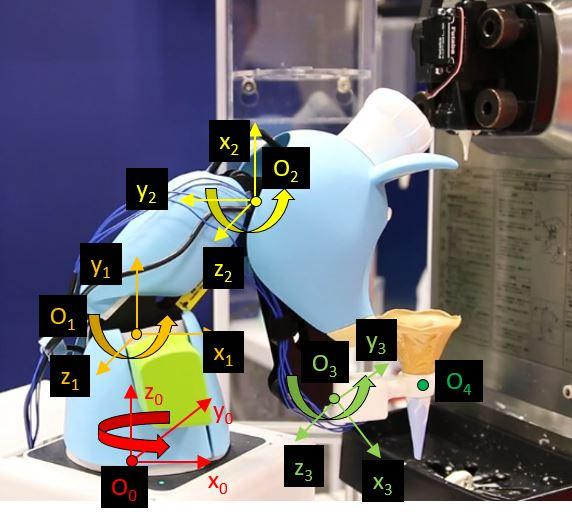

*Figure XX: The robot arm in action with assigned DH frames*

This is a RRRR style manipulator. Below we show the frames and joint angles in home configuration. Note that $O_3$ is at an angle $\gamma$ from the vertical with respect to $O_2$. 

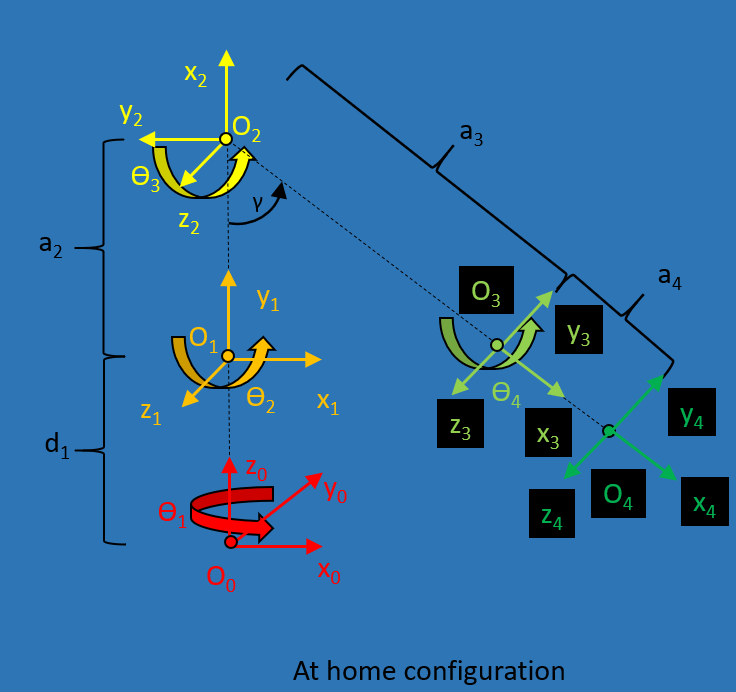

*Figure 1: DH Convention assigned frames*

We first explain how the frames were chosen using the DH convention described in pages 86-87 in [Robot Modeling and control ###]:

- There are 4 revolute joints and so the z-axes are positioned on the axis of revolutions for these 4 joints ($\left.z_0 ,z_1 ,z_2 ,z_3 \right)\ldotp$

- We establish the base frame ($\left.O_0 \right)$ at ground level and use a right-hand coordinate system and arbitrarily choose direction of $x_0 ,y_0$ for convenience.

- To find the origin of $O_1$ we find the intersection of $z_0$ and $z_1$. To find the origin of $O_2$, we follow the normal between the parallel axes $z_1$ and $z_2$. To find $O_3$, we similarly follow the normal between the parallel axes $z_2$ and $z_3$. $O_4$ is attached to the end-effector. The orientation of the end-effector is identical to $O_3$ (in home config).  

- To find the x-axis of Frame 1, we choose $x_1$ to be perpendicular to $z_0$ and attached to $O_1$. Similarly, to find the x-axis of Frame 2, we choose $x_2$ to be perpendicular to $z_1$ and attached to $O_2$. $x_3$ is along the common normal between $z_2$ and $z_3$ as per DH convention. 

- We find $y_1$ and $y_2$ to complete the right-hand coordinate frames.

We can then proceed with the following steps to obtain the homogeneous transformation matrix that describes the end-effector position and orientation with respect to the base frame:

- Create the DH parameter table, described below.

- Substitute the values from DH parameter table into Equation 3.10 in [1], described below.

- Construct $T_4^0 =A_1 A_2 A_3 A_4$.

To construct the DH parameter value, we list what each parameter describes:

- $\alpha_i \;$: rotate $x_i$ so that $z_{i-1}$ aligns $z_i$

- $\theta_i \;$: rotate $z_{i-1} \;$so that $x_{i-1}$ aligns $x_i$

- $d_i$: displacement along $z_{i-1}$ from $O_{i-1}$ to $O_i$

- $a_i$: displacement along $x_i$ from $O_{i-1}$ to $O_i$

First we look at $a_i$. For link 1, there is no displacement from $O_0$ to $O_1$ along $x_0$ so $a_1 =0$. From $O_1$ to $O_2$ along $x_1$, the displacement is  $a_2$. Similarly, from $O_2$ to $O_3$ along $x_2$, the displacement is $a_3$. Lastly, from $O_3$ to $O_4$ along $x_3$, the displacement is $a_4$.

Now we look at $\alpha_i$. For link 1, to align $z_0$ and $z_1$ about $x_1$ requires 90 deg rotation counter-clockwise (positive rotation). $z_1 ,z_2 ,z_3$ are all parallel, so $\alpha_2 =\alpha_3 =\alpha_4 =0$.

Now we look at $d_i$. For link 1, the displacement from $O_0$ to $O_1$ along $z_0$ is $d_1$. There is no displacement from $O_1$ to $O_2$ along $z_1$ or from $O_2$ to $O_3$ along $z_2$ or from $O_3$ to $O_4$ along $z_3 \;$so $d_2 =d_3 =d_4 =0$.

Lastly, since we aligned the rotation axes of all 3 revolute joints with $z_i$ for i=1,2,3 this corresponds to $\theta_1 ,\theta_2 ,\theta_3$. However, there is a positive rotation of  $\frac{\pi }{2}$  to align $x_1$ and $x_2$ and a negative rotation of  $\frac{\pi }{2}+\gamma \;$ to align $x_2$ and $x_3$. The full DH parameter list is summarized in the table below:

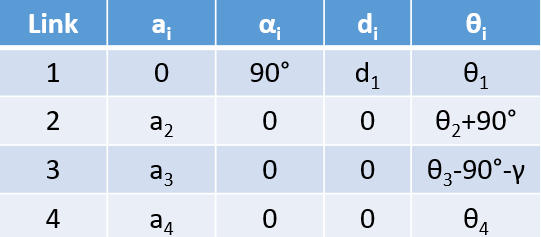

*Figure 2: DH Table for our robotic arm*

We use the values from DH parameter table above in the general form of the homogeneous transformation matrix $A_i$, given in Eq. 3.10 in [1]:


$$A_i =\left\lbrack \begin{array}{cccc}
c\theta_i  & -s\theta_i c\alpha_i  & s\theta_i s\alpha_i  & a_i c\theta_i \\
s\theta_i \; & c\theta_i c\alpha_i  & -c\theta_i s\alpha_i  & a_i s\theta_i \\
0 & s\alpha_i \; & c\alpha_i \; & d_i \\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$


The foSubstituting the values for each link leads to:


$$A_1 =\left\lbrack \begin{array}{cccc}
c\theta_1  & 0 & s\theta_1  & 0\\
s\theta_1 \; & 0 & -c\theta_1  & 0\\
0 & 1 & 0\; & d_1 \\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$



$$A_2 =\left\lbrack \begin{array}{cccc}
c\left(\theta_2 +\frac{\pi }{2}\right) & -s\left(\theta_2 +\frac{\pi }{2}\right) & 0 & a_2 c\left(\theta_2 +\frac{\pi }{2}\right)\\
s\left(\theta_2 +\frac{\pi }{2}\right)\; & c\left(\theta_2 +\frac{\pi }{2}\right) & 0 & a_2 s\left(\theta_2 +\frac{\pi }{2}\right)\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$
 


$$A_3 =\left\lbrack \begin{array}{cccc}
c\left(\theta_3 -\frac{\pi }{2}-\gamma \right) & -s\left(\theta_3 -\frac{\pi }{2}-\gamma \right) & 0 & a_3 c\left(\theta_3 -\frac{\pi }{2}-\gamma \right)\\
s\left(\theta_3 -\frac{\pi }{2}-\gamma \right)\; & c\left(\theta_3 -\frac{\pi }{2}-\gamma \right) & 0 & a_3 s\left(\theta_3 -\frac{\pi }{2}-\gamma \right)\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$



$$A_4 =\left\lbrack \begin{array}{cccc}
c\theta_4  & -s\theta_4  & 0 & a_4 c\theta_4 \\
s\theta_4  & c\theta_4  & 0 & a_4 s\theta_4 \\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$


We can then construct the homogeneous transformation matrix that describes the position and orientation of the end-effector frame to the base frame by composing the transformation matrices between each frame as follows:

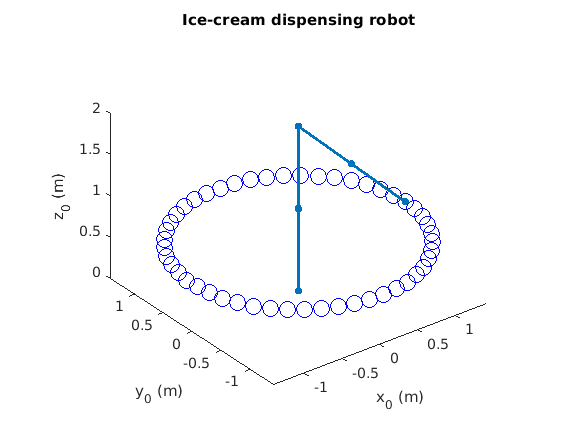

*Figure 2: Ice-cream dispensing robot simulation*

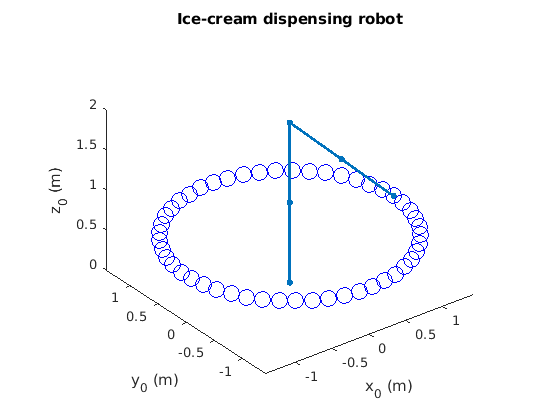

clear all; close
d1=1; a2=1; a3=1; a4=1; gamma=pi/4;
intervals = 50;
theta1_vec = linspace(0,2*pi,intervals);
theta2_vec = linspace(0,0,intervals); 
theta3_vec = linspace(0,0,intervals);
theta4_vec = linspace(0,0,intervals);

for i=1:length(theta1_vec)
    a_vec = [0, a2, a3, a4]; 
    alpha_vec = [pi/2, 0, 0, 0]; 
    d_vec = [d1, 0, 0, 0]; 
    theta1=theta1_vec(i); theta2=theta2_vec(i); theta3=theta3_vec(i); theta4=theta4_vec(i);
    theta_vec = [theta1, theta2 + pi/2, theta3 - pi/2 - gamma, theta4];
    [H, P_vec, All_H] = DHmatrix(a_vec,d_vec,alpha_vec,theta_vec); 
    plot_link(P_vec,i,intervals);
end
xlabel('x_0 (m)'); ylabel('y_0 (m)'); zlabel('z_0 (m)'); title('Ice-cream dispensing robot')

### Jacobian and Singularities

From the DH table that we've generated for the robotic arm, we can generate the Jacobian for the arm. Once we have the Jacobian, we can determine both end effector velocities (linear and angular) as well as try to find if any singularities exist within the arm design.

The Jacobian of our arm will be a 6x4 matrix - 3 rows for each of the linear and angular velocities, and then a column for each joint on the robotic arm. Typically, the equations for the Jacobian of a given robotic joint are, for prismatic joints:


$$J_i =\left\lbrack \begin{array}{c}
z_{i-1} \\
0
\end{array}\right\rbrack$$


...and for revolute joints, the Jacobian is found through:


$$J_i =\left\lbrack \begin{array}{c}
z_{i-1} \times \left(o_n -o_{i-1} \right)\\
z_{i-1} 
\end{array}\right\rbrack$$


Our arm is a four axis robot with each joint being a revolute joint. As such, the equation for the Jacobian that we'll use is:


$$J=\left\lbrack \begin{array}{cccc}
z_0 \times \left(o_4 -o_0 \right) & z_1 \times \left(o_4 -o_1 \right) & z_2 \times \left(o_4 -o_2 \right) & z_3 \times \left(o_4 -o_3 \right)\\
z_0  & z_1  & z_2  & z_3 
\end{array}\right\rbrack$$


When a Jacobian's determinant is equal to 0, the Jacobian is of a lower rank than the number of joints in the robot. As such, we have achieved a singularity. Unfortunately, the Jacobian for a 4 axis arm is not square, so we can not make use of the determinant of the Jacobian. We can, however, make use of two approaches that will allow us to utilize this methodolgy.

The first is that the first axis, $o_0$, acts as a rotation around the Z axis of the base frame. No other joint moves along this axis, and thus the links of the robot arm cannot form a singularitiy based on input from the first axis. Thus, we can ignore this axis when considering the Jacobian purely for singularities.

The other aspect that we can utilize is that the Jacobian can be decoupled. We will break the Jacobian into two square 3x3 matricies - the top matrix, $J_l$, consisting of the linear velocities and the bottom matrix, $J_a$consisting of the angular velocities. Therefore:


$$J=\left\lbrack \begin{array}{c}
J_l \\
J_a 
\end{array}\right\rbrack$$


$J_l$ and $J_a$ are square matricies, and thus our determinant heck **[what word did you mean instead?]** can work. Here, if either $J_l$ or $J_a$ have a determinant of 0, we have reached a singularity.

We can also use **singular value decomposition**, or **SVD**, to determine if the Jacobian matrix is close to losing rank. Finding the minimum in the resulting SVD of the Jacobian is also sign that the Jacobian matrix is close to being non-invertible and thus a singular configuration is achieved.

Unfortunately, with our 4 axis arm configuration, with 3 serial joints with parallel z-axis, our arm is always in a singular configuration. No matter the position of the arm, we do not have enough degrees of freedom for our robot arm configuration to avoid constantly being at a singularity in 3d space.

### Inverse Kinematics

Inverse kinematics (IK) is the opposite of forward kinematics (FK). In IK, the desired end effector position is known and the goal is to calculate the joint variables necessary to reach that desired position. There are several methods used for solving the IK of a robotic system. In this project, we will be exploring two of these methods: the geometric approach and the numerical approach. The results of these two methods are then compared. 

#### **Numerical IK**

We will first begin to discuss the numerical approach that was used to calculate the inverse kinematics of the system. Numerical IK, iteratively tries to solve for the best matching solutions, or joint values, within a given error margin for the given desired end effector position. This method is more computationally expensive than the geometric approach but it is widely used in industry and allows for a streamlined way of analyzing complex systems where a geometric approach would be too difficult. 

The steps to conduct a numerical inverse kinematic analysis include:

- Extract $J_v$, the upper half of the jacobian matrix, this portion relates to the linear velocity of the end effector.

- Provide the desired end effector position, $p_d$.

- Make an initial guess, $q_0$, for the joint angles that will be solved numerically. 

- For the first iteration we set the calculated instant angles, $q_q$, equal to the initial guess. 

- Extract $p_e$, the position column vector from the homogeneous transformation matrix (HTM) which describes the end effector frame relative to the base frame of the robot, $T_{04}$. 

- Computer error in calculation, compare the distance difference between the desired position, $p_d$, and the calculated position,$p_e$.

- Create loop that will run until an error value lower than the set threshold is achieved.

- In the loop, the current jacobian, $J_{\textrm{vi}}$, is computed for the current joint configurations, $q_q$.

- The step factor for the loop, $\delta_q$, is calculated by taking the inverse of the current jacobian and multiplying it by the error calculated.

- The new joint angles, $q_q$, are then calculated by adding the step factor to the current joint angle.

- The new end effector position,$p_e$, is then calculated using the new joint angles.

- Calculated the error, the difference between the new end effector position and the desired position.

- Loop will repeat until it breaks when the error reaches the threshold value.

Now that the code in order to calculate for  inverse kinematics of the system has been developed, the joint positions corresponding to certain desired positions can be calculated numerically. 

#### **Geometric IK**

We will now be discussing the geometric approach taken to calculate the inverse kinematics of the system. Figure X, below depicts the geometric shapes analyzed in order to obtain the value of the first joint variable. 

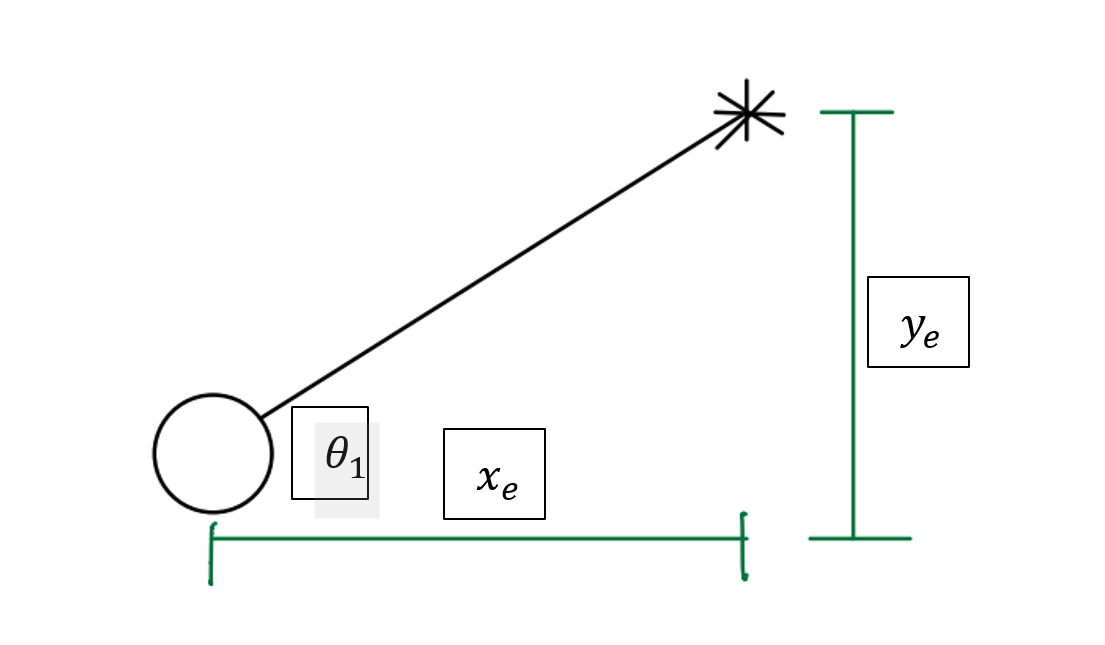

*Figure 3: Geometrics shapes and variables used to calculate the value of the first joint angle*

Solving for this variable was straightforward, as it could be solved with just one simple trigonometry calculation, see equation below. 


$$\theta_1 =\mathrm{atan2}\;\left(y_e ,x_e \right)$$
         

Solving for the other joint variables was not as straightforward as solving for the first, as they involved more geometric equations. To solve for the other angles, the diagram of the system was divided into 4 different triangles. Figure x, below shows the first triangle that was analyzed.

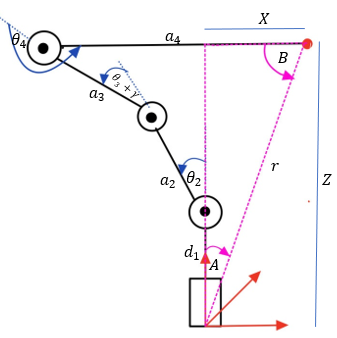

*Figure 4: Diagram of the first triangle analyzed in the Inverse Kinematic analysis*

First the resultant, r, between the base of the system and position of the end effector was solved for using the pythagorean theorem.


$$r=\sqrt{x^2 +z^2 \;}$$


Then angles A and B were solved for by using the law of cosines, and relationships between the angles of a triangle.

 
$$A=\textrm{atan2}\;\left({y\;,x} \right)$$
 


$$B=90-A$$


Now that the components of the first trangle were solved for, the components for the second triangle, Figure x, could now be solved for. 

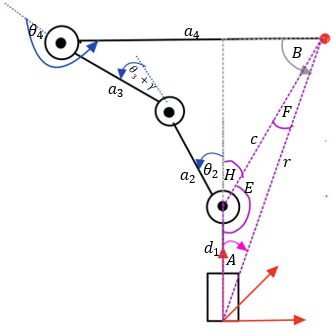

*Figure 5: Second triangle analyzed during the inverse kinematics analysis*

The triangle side, c, was solved for using the equation below. Using the side c, the law of sines can be applied to solve for the angle E, which is supplementary with angle H. Then angle F was calculated by subtracting E and A from 180 degrees


$$c=\sqrt{d_1^2 +r^2 -2\;d_1 \;r\;\cos \left(A\right)}$$



$$E=\sin^{-1} \left(\frac{r\;\sin \left(A\right)}{c}\right)$$



$$H=180-E$$



$$F\;=180-\left(\;E+A\;\right)$$


The third triangle diagram, below, was also analyzed for the IK.

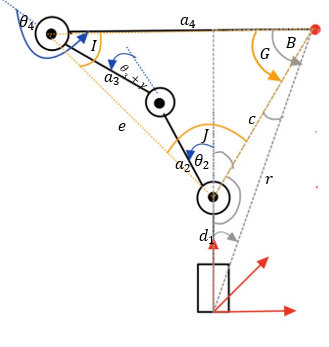

*Figure 6: Third triangle analyzed for the IK analysis*

In this third diagram, angle G was solved for by subtracting angle F from B.  Then side e was solved for by using the law of cosine. Then the law of sines was used to solve for angle J. Finally angle I was solved for by subtracting angles J and G from 180 degrees. 


$$G=B-F$$



$$e=\sqrt{a_4^2 +c^2 -2\;a_4 \;c\;\cos \left(G\right)}$$



$$J=$$
 
$$\sin^{-1} \left(\frac{a_4 \;\sin \left(G\right)}{e}\right)$$



$$I=180-\left(J+G\right)$$


The fourth triangle, depicted below, was the final triangle used in the inverse kinematic analysis.  

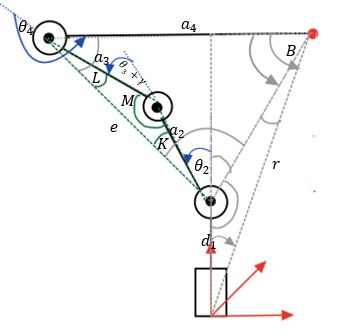

*Figure 7: Fourth triangle analyzed for the IK analysis*

Using this triangle, angle M was solved for using the law of cosines. Then using the law of sines, angle L was calculated and finally angle K was determined by subtracting angles L and K from 180 degrees.


$$M=\cos^{-1} \left(\frac{a_3^2 +a_2^2 -e^2 }{2\;a_3 a_2 }\right)$$



$$L=\sin^{-1} \left(\frac{a_2 \;\sin \left(M\right)}{e}\right)$$



$$K=180-\left(L+K\right)$$


Finally now with all of these parameters, the rest of the joint angles can be solved for using algebra:


$$\theta_2 =J-\left(K+H\right)$$



$$\theta_3 =180-M-\gamma$$



$$\theta_4 =\left(I-L\right)\;+180$$


Now using these equations, the joint variables can now be calculated for any desired position. 

In order to verify that these equations are correct, we used forward kinematics to calculate the position associated with calculated configuration. We then compared this position vector to the desired positon. 

### Trajectory Planning

Here we will describe our approach to trajectory planning for the ice-cream dispensing robot arm. There are a maximum of 6 desired end-effector points: home, cone dispenser, flavor 1, flavor 2, flavor 3, and customer drop-off. Each cycle begins with the end-effector at the home config, then cone dispenser, a combination of flavors, customer drop-off, and then back at home. This simplifies our trajectory planning problem since some paths repeat every cycle. 

The steps for trajectory planning are given as follows:

- Use numerical inverse kinematics to find singularity-free joint angles that correspond to the end-effector at each of the 6 points.

- Generate a singularity-free minimum time trajectory from home to cone dispenser and from customer drop-off to home.

- Depending on customer choice of flavors, generate singularity-free minimum time trajectories from cone dispenser to first flavor, between flavors, and then to customer drop-off.

- Combine trajectories in correct order and execute motion.

- Repeat steps 3-4 for next cycle depending on customer input.

We use a minimum-time trajectory to optimize the cycle time. Given a constant acceleration, this specifies the shortest trajectory time by starting the trajectory at maximum acceleration ($+\alpha$) until an appropriate switching time, at which point we instantly switch to minimum acceleration ($-\alpha$). Since each trajectory requires zero velocity at the beginning and end, the switching time occurs at half the total trajectory time. Let $t_0$ be the start time and $t_f$ be the end time of the trajectory. We know from trajectory symmetry that the switching time $t_s =\frac{t_f -t_0 }{2}$. Let the velocity at the switching time be $V_s$ and for constant acceleration, we have $V_s =\alpha t_s$. Let $q_0$ and $q_f$ be the initial and final configuration. At the switching time, we have: $V_s =\frac{q_f -q_0 }{t_s }=\alpha t_s \;$. This leads to $t_s =\sqrt{\frac{q_f -q_0 }{\alpha }}$. 

We consider a simple example where we are asked to find a trajectory from home configuration $\theta_1 =0$ to a desired configuration $\theta_1 =\frac{\pi }{2}$ within 5 sec with a maximum joint angle acceleration $\alpha =20\;\frac{\deg }{s^2 }$. We can treat each joint motion as an independent trajectory, so this method can scale for other joints as well. The trajectory needs to be checked to ensure no singularities are crossed (described earlier, but not considered in this example). 

For $\theta_1$, $t_s =\sqrt{\frac{q_f -q_0 }{\alpha }}=\sqrt{\frac{\frac{\pi }{2}-0}{20}}=2\ldotp 12\;\sec$, which leads to $t_f =4\ldotp 24\;\sec$ (within our 5 sec specification). The angular velocity of joint 1 in the accelerating segment of the trajectory is simply given by $V_1 =\alpha t$, leading to joint angle equation of $\theta_1 =\frac{\alpha t^2 }{2}$. For the decelerating segment, the angular velocity of joint 1 is given by $V_1 =V_s -\alpha \left(t-t_s \right)=\alpha t_s -\alpha \left(t-t_s \right)=2\alpha t_s -\alpha t$. Integrating this with the appropriate initial condition leads to $\theta_1 =$$-\frac{\alpha t^2 }{2}+2\alpha t_s t^2 -\alpha t_s^2$. We can plot the angular position and velocity profiles below:

figure
qs=0; qf=pi/2; alpha=deg2rad(20);
ts=sqrt((qf-qs)/alpha);
interval=20;
t1=linspace(0,ts,interval);
t2=linspace(ts,2*ts,interval);
ang_pos1 = 0.5*alpha*t1.^2;
ang_pos2 = -0.5*alpha*t2.^2 + 2*alpha*ts*t2 - alpha*ts^2;
ang_vel1 = alpha*t1;
ang_vel2 = 2*alpha*ts - alpha*t2;
t=[t1,t2];
ang_pos=rad2deg([ang_pos1,ang_pos2]);
vel_pos=rad2deg([ang_vel1,ang_vel2]);
subplot(1,2,1)
plot(t,ang_pos); xlabel('Time (sec)'); ylabel('Angular position (deg)')
subplot(1,2,2)
plot(t,vel_pos); xlabel('Time (sec)'); ylabel('Angular velocity (deg/sec)')

The trajectory generated matches our desired specification. The velocity profile is piece-wise linear and changes slope at the switching time. The angular position accelerates and decelerates in a smooth motion. We can visualize $\theta_1$ in the ice-cream robot following this motion as follows:

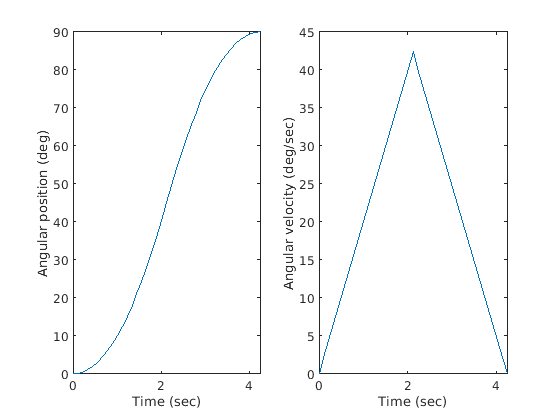

figure
d1=1; a2=1; a3=1; a4=1; gamma=pi/4;
theta1_vec = deg2rad(ang_pos);
for i=1:length(theta1_vec)
    a_vec = [0, a2, a3, a4]; 
    alpha_vec = [pi/2, 0, 0, 0]; 
    d_vec = [d1, 0, 0, 0]; 
    theta1=theta1_vec(i); 
    theta_vec = [theta1, 0 + pi/2, 0 - pi/2 - gamma, 0];
    [H, P_vec, All_H] = DHmatrix(a_vec,d_vec,alpha_vec,theta_vec); 
    plot_link(P_vec,i,length(theta1_vec));
end

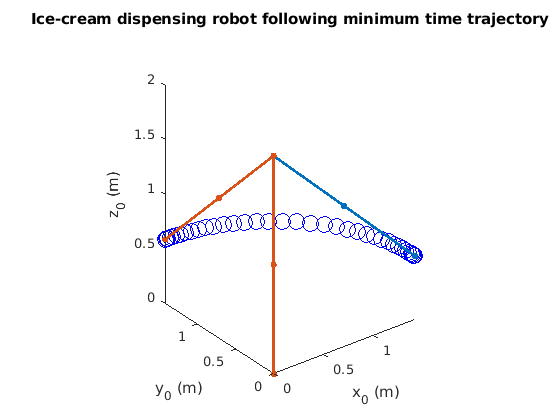

xlabel('x_0 (m)'); ylabel('y_0 (m)'); zlabel('z_0 (m)'); title('Ice-cream dispensing robot following minimum time trajectory')

We can see the end-effector points are spaced tighter at the beginning and end and looser in the middle of the motion, indicating the accelerating and decelerating motion.

### Collision Detection

Here we discuss our approach to collision detection of a moving obstacle for the ice-cream dispensing robot. In this context, the moving obstacle can resemble a human in the vicinity of the robot that is being monitored by a vision system that is able to continuously feed the position information of the human back to the robot controller. 

Here we consider a moving obstacle in the form of a sphere, since any obstacle can modeled/approximated as a union of spheres and calculating the distance from each sphere to the manipulator is a fairly low cost computation. Furthermore, this result can be extended to more general shaped obstacles as well. 

Our approach consists of segmenting each link in the manipulator $n$ times and then calculating the Euclidean distance between a point on each segment (for convenience, say the beginning of each segment) and the center of the obstacle. If this distance is less than the radius of the sphere (or radius + some safety distance), then the manipulator is in collision. This is visually represented below:

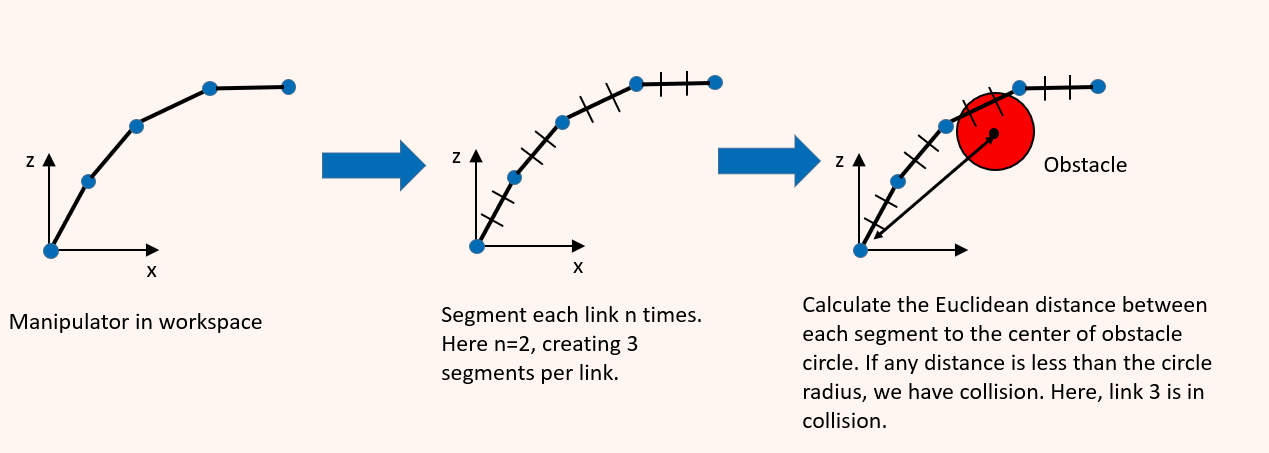

*Figure 8: An explanation of our numerical method*

Given the position of each link (from forward kinematics), we can segment each link as follows. Suppose link $i$ begins at $\left(x_1 ,y_1 ,z_1 \right)$ and ends at $\left(x_2 ,y_2 ,z_2 \right)$ and we would like to segment this link $n$ times. Segmenting $n$ times results in $n+1$ segments. The end of segment 1 is given by $\left(x_1 +\frac{x_2 -x_1 }{n+1},y_1 +\frac{y_2 -y_1 }{n+1},z_1 +\frac{z_2 -z_1 }{n+1}\right)$. By extension, the start of segment $i$ is given by $\left(x_1 +i\frac{x_2 -x_1 }{n+1},y_1 +i\frac{y_2 -y_1 }{n+1},z_1 +i\frac{z_2 -z_1 }{n+1}\right)$. 

The Euclidean distance between the center of the sphere and a segment of the manipulator is calculated by $d_{\textrm{ij}} =\sqrt{{\left(x_c -x_{\textrm{ij}} \right)}^2 {+\left(y_c -y_{\textrm{ij}} \right)}^2 {+\left(z_c -z_{\textrm{ij}} \right)}^2 }$. Here $d_{\textrm{ij}}$ is the distance from the center of the sphere at $\left(x_c ,y_c ,z_c \right)$ to segment $j$ of link $i$. Each loop, we compute $d_{\textrm{ij}}$ for all i links and j segments per link and check if the minimum of this is less than the obstacle radius: $\min \left(d_{\textrm{ij}} \right)<r$. If so, the manipulator is in collision with the obstacle space. 

## Results

In this section, we will apply what we discussed above towards our application of the ice cream robot arm.

### Inverse Kinematics

In this portion of the results, a kinematic analysis will be conducted on the system using two different methods: numerical and geometric inverse kinematics.

#### Numerical Inverse Kinematics 

The numerical Inverse kinematic approach involves using the jacobian matrix of the system in order to help calculate the step factor of the system. Due to this, we first did the forward kinematics and calculated the Jacobian for the system.

clc; clear ;
syms theta1 theta2 theta3 theta4
d1=1; a2=1; a3=1; a4=1; gamma=pi/4;    
a = [0, a2, a3, a4]; 
alpha = [pi/2, 0, 0, 0]; 
d = [d1, 0, 0, 0];
theta = [theta1, theta2 + pi/2, theta3 - pi/2 - gamma, theta4];


A = GetDHrad(a, alpha, d, theta) 

A = 1×4 cell array
    {4×4 sym}    {4×4 sym}    {4×4 sym}    {4×4 sym}


T01 = simplify(A{1});
T02 = simplify(A{1}*A{2});
T03 = simplify(A{1}*A{2}*A{3});
T04 = simplify(A{1}*A{2}*A{3}*A{4})

Ts={T01 T02 T03 T04};

dh_table = {
             [theta1                d1      0       0],
             [theta2+(pi/2)         0       a2      0],
             [theta3-(pi/2)-gamma   0       a3      0],
             [theta4                0       a4      0],
           };
Jac = simplify(jacobian_from_dh_table(dh_table, true));

We then use the the Jacobian that was calculated and extract the upper portion of the Jacobian, or Jv. 

Jv = Jac(1:3,1:4);
%Jv = subs(Jv, [d1, a2 , a3, a4], [1,1,1,1]);
%Jv= jacobian(pe, [theta1,theta2,theta3,theta4]);

This numerical approach to solving for the inverse kinematics of the system uses gradient decent. The position and joint values are iteratively calculated until the error falls below the assigned threshold error value.

Then we define the other important parameters for the calculation, such as:

**pd**: The desired position

**q0**: The initial guess for the calculation

**error**: The error which will be minimized in this calculation. This calculates the difference between the desired value and the current value obtained through the numerical calculation.

We also define the functions for this calculation.

**f_pe: **Function to calculate the position vector for every configuration.

**f_Jv: **Function to calculate the jacobian for the current configuration.

pe = T04(1:3, 4);

vanilla = [0.4, 0.4, 0.4]';  % 1   
chocolate = [0.6,0.6, 0.6]'; % 2
mango = [0.8, 0.8,0.8]'; % 3
pd = mango

pd =     0.6000
    0.6000
    0.6000


q0 = [0;0;0;0];
qq = q0 ; 
f_pe = matlabFunction(pe);
pei = f_pe (qq(1), qq(2),qq(3), qq(4));
error = pd - pei ;
f_Jv = matlabFunction(Jv);
best_er = error;
norm(best_er);
i = 0;
count = 1

count = 1

This loop uses the upper jacobian matrix to solve for the step factor of the calculation and then uses that to calculate the step factor of the joint variables. 

After this, the new joint angle is calculated, qq. Then these angles are inputed into the Forward Kinematic function,  f_pe, to evaluate the position that results from the calculated configuration.

The error is then calcuated between the desired position and this new calculated position.

This loop will continue until the error value is below the threshold value or when the error asymptotes.

while norm (error) > 0.1
    i = i +1;
    Jv_q = f_Jv(qq(1), qq(2),qq(3), qq(4));
    delta_q = pinv(Jv_q)*error ;
    qq = qq + delta_q;
    pei = f_pe (qq(1), qq(2),qq(3), qq(4));
    error = pd - pei;
    norm(error);
    
    if abs(norm(error)-norm(best_er)) < 0.001 % if error is about the same as best error 
       count = count +1; % count it
    end
    if norm(error) < norm(best_er) % if error is less or better than best error 
       best_er = error; % make this error the new best error 
       count = 1; % reset counter
       norm(best_er);
    end
    if count > 100 % the amount of times i let the loop repeat before breaking loop
        break % end loop 
    end
end

The results of this calculation are the approximate joint values needed to attain thedesired position. 

pd

pd =     0.6000
    0.6000
    0.6000


disp('Numerical Approach')

Numberical Approach


error =norm(best_er)

error = 0.4005

qq1 = qq

qq1 =     0.7646
    0.7646
    0.1528
   -1.1213


qq1(4) = (pi/2)- ( qq(2) + gamma + qq(3))

qq1 =     0.7646
    0.7646
    0.1528
   -0.1320


f_pe(qq1(1), qq1(2), qq1(3), qq1(4))

ans =     0.3470
    1.5148
    1.0234


### Geometric Inverse Kinematics 

The geometric approach of obtaining the inverse kinematics of this proble, involves using trigonometric and geometric rules to solve for the joint angles. Some of the rules or methods that were used for this analysis include :

- law of cosines

- law of sines 

- triangle rules

First, FK was used and defined the position vector of the end effector of the system.

clc; clear ;
syms theta1 theta2 theta3 theta4

d1=1; a2=1; a3=1; a4=1; gamma=45;    

pex =   + a2*sind(theta2) + a3*sind(theta2 + theta3 + gamma) + a4*sind(theta2 + theta3 + gamma +theta4 );
pey = pex * tand(theta1);
pez = d1 + a2 * cosd(theta2) +a3 * cosd(theta2 + theta3 + gamma) + a4*cosd(theta2 + theta3 + gamma +theta4 );
pe = [ pex; pey; pez];

Then the desired position was chosen and divided into components.

vanilla = [0.4, 0.4, 0.4]';  % 1   
chocolate = [0.6,0.6, 0.6]'; % 2
mango = [0.8, 0.8,0.8]'; % 3
pd = [3;0;1]

pd =      3
     0
     1


x = pd (1);
y = pd (2);
z = pd (3);

First we solve for the first joint angle by using trigonometry to relate the sides of the triangle, seen from the top view ( XY plane) of the robot, to the first joint angle.

th1 = round(real(atan2d( y, x)),2);

Now, the rest of the joints angles can be  solved using the lateral view, XZ plane, of the robot. 

Using the second triangle, the components of the big right triangle, who's hypothenuse connects the base to the end effector position, were solved for. To solve for the hypothenuse of the triangle, pythagorean theorem was used. To solve for one of its angles, A, trigonometric relations were used. Then angle B was found by subtracting angle A from 90.

r = sqrt ( x^2 + z^2 );
A = round(real(atan2d(x,z)),2);
B = 90 - A;

Next the components of the second triangle were solved for. This triangle shares angle A and the resultant, r, of the previous triangle. We solved for one of the sides of this triangles using the law of cosines  and its angles using law of sines.Then we solve for angle H using that facting the it was supplementary with angle E

c = round(real(sqrt(d1^2 +r^2 - 2*d1*r*cosd(A))),2);
E = round(real(asind((r*sind(A))/c)),2);
F = 180 - (E + A);
H = 180 - E;

Then we solved for the components of the third triangle. This involved solving for the of the the sides of the triangle, e, using law of cosines  and then solving for  three of its angles (G, J and I) using law of cosines and triangle relationships

G = B - F ;
e = round(real(sqrt(a4^2 +c^2 - 2*a4*c*cosd(G))),2);
I = round(real(asind((c*sind(G))/e)),2);
J = 180 - (I + G );

For the Fourth triangle, the angle M was solved for using the law of cosines. Angle L was calcualted using the law of sines and angle K was found by subtracting angles L and k from 180.

M = round(real(acosd((a2^2 + a3^2 - e^2)/(2*a2*a3))),2);
K = round(real(asind((a3*sind(M))/e)),2);
L = 180 - ( M + K );

Now with all these solved components, the rest of the joint angles can be solved for simply using  simple algebra.

th2 = J - (H + K);
th3 = 180 - M - gamma ;

To solve for the fourth angle, the fact the the fourth link is always paralel to the ground was used. 

th4 =  90 - (th2 + th3 + gamma ); %180 + (I - L);

Here we display the resultant angles:

th1, th2, th3, th4 

th1 = 0

th2 = 90

th3 = -45

th4 = 0

Finally, we substituted these values into forward kinematics in order to obtain the the position that results from this joint configuration and confirm that they match.

pei = double(subs(pe, {theta1, theta2, theta3, theta4}, { th1, th2, th3, th4}))

pei =      3
     0
     1


### Jacobian and Singularities

We are going to represent our Jacobian first symbollically, and then numerically to prove that we are always in a singular configuration. First, we shall find the analytical symbolic representation of our Jacobian. To see how we generate this, please refer to the *jacobian_from_dh_table* function defined below.

syms theta1 theta2 theta3 theta4 gamma d1 a2 a3 a4

dh_table = {
             [theta1                d1      0       0],
             [theta2+(pi/2)         0       a2      0],
             [theta3-(pi/2)-gamma   0       a3      0],
             [theta4                0       a4      0],
           };

j = jacobian_from_dh_table(dh_table, true)

$$j = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{1} & \sigma_{1} & -\sigma_{3}-a_{3}\,\sin\left(\theta_{1}-\gamma +\theta_{2}+\theta_{3}\right) & -\sigma_{3}\\ \sigma_{2} & \sigma_{2} & \sigma_{4}+a_{3}\,\cos\left(\theta_{1}-\gamma +\theta_{2}+\theta_{3}\right) & \sigma_{4}\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 1 & 1 & 1 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\sigma_{3}-a_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)-a_{3}\,\sin\left(\theta_{1}-\gamma +\theta_{2}+\theta_{3}\right)\\ \sigma_{2}=\sigma_{4}-a_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)+a_{3}\,\cos\left(\theta_{1}-\gamma +\theta_{2}+\theta_{3}\right)\\ \sigma_{3}=a_{4}\,\sin\left(\theta_{1}-\gamma +\theta_{2}+\theta_{3}+\theta_{4}\right)\\ \sigma_{4}=a_{4}\,\cos\left(\theta_{1}-\gamma +\theta_{2}+\theta_{3}+\theta_{4}\right) \end{array}$$

Here we see our resulting analytical representation of the Jacobian.


$$\begin{array}{l}
\left(\begin{array}{cccc}
\sigma_1  & \sigma_1  & -\sigma_3 -a_3 \,\sin \left(\theta_1 -\gamma +\theta_2 +\theta_3 \right) & -\sigma_3 \\
\sigma_2  & \sigma_2  & \sigma_4 +a_3 \,\cos \left(\theta_1 -\gamma +\theta_2 +\theta_3 \right) & \sigma_4 \\
0 & 0 & 0 & 0\\
0 & 0 & 0 & 0\\
0 & 0 & 0 & 0\\
1 & 1 & 1 & 1
\end{array}\right)\\
\mathrm{}\\
\textrm{where}\\
\mathrm{}\\
\;\;\sigma_1 =-\sigma_3 -a_2 \,\cos \left(\theta_1 +\theta_2 \right)-a_3 \,\sin \left(\theta_1 -\gamma +\theta_2 +\theta_3 \right)\\
\mathrm{}\\
\;\;\sigma_2 =\sigma_4 -a_2 \,\sin \left(\theta_1 +\theta_2 \right)+a_3 \,\cos \left(\theta_1 -\gamma +\theta_2 +\theta_3 \right)\\
\mathrm{}\\
\;\;\sigma_3 =a_4 \,\sin \left(\theta_1 -\gamma +\theta_2 +\theta_3 +\theta_4 \right)\\
\mathrm{}\\
\;\;\sigma_4 =a_4 \,\cos \left(\theta_1 -\gamma +\theta_2 +\theta_3 +\theta_4 \right)
\end{array}$$


Earlier, we discussed how ew are always in a singular configuration. To prove this, select any combination of angles for our given joints - we shall demonstrate how, regardless of your configuration, we will be in a singular configuration.

theta1 = 45;
theta2 = 45;
theta3 = 32;
theta4 = 81;
gamma = 90;
d1 = 1;
a2 = 1;
a3 = 1;
a4 = 1;

Given this configuration, we will find the numerical Jacobian for this configuration. First, we create a DH table with values representing the chosen configuration.

dh_table = {
             [theta1                d1      0       0],
             [theta2                0       a2      0],
             [theta3-90-gamma       0       a3      0],
             [theta4                0       a4      0],
           };

Here, we can calculate our resultant numerical Jacobian:

j = jacobian_from_dh_table(dh_table)

j =    -0.5427   -0.5427    0.4573   -0.3907
    1.4504    1.4504    1.4504    0.9205
         0         0         0         0
         0         0         0         0
         0         0         0         0
    1.0000    1.0000    1.0000    1.0000


Once we have that, we can prove either through looking at SVD or decoupling our above Jacobian via the last three links, we are always in a singular configuration.

j_svd = svd(j)

j_svd =     3.3671
    0.8373
    0.2658
         0


min(j_svd)

ans = 0


j_l = j(1:3, 2:4)

j_l =    -0.5427    0.4573   -0.3907
    1.4504    1.4504    0.9205
         0         0         0


j_a = j(4:6, 2:4)

j_a =      0     0     0
     0     0     0
     1     1     1



det(j_l)

ans = 0

det(j_a)

ans = 0

### Trajectory Planning

Here we will generate a minimum time trajectory for all joints based on user-input of ice-cream flavors. The manipulator begins at home configuration, then moves to the cone dispensing station. Then depending on user-input, the end-effector is moved to upto 3 locations, corresponding to each flavor, in the requested order (Flavor 1 at the bottom of the cone, Flavor 3 at the top). The manipulator will pause at each dispensing location for a set amount of time.  We also draw the last link configuration at each station to better visualize the overall trajectory. 

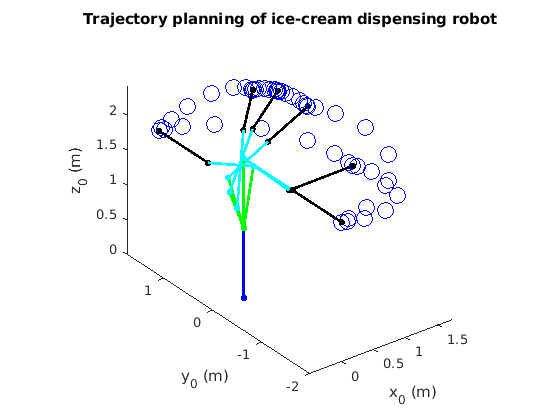

*Figure 9: The finished trajectory plans of various key positions of the arm*

clear all 
close all

Flavor_1=3;
Flavor_2=2;
Flavor_3=1;

Q_mat = look_up_joint_angles(Flavor_1,Flavor_2,Flavor_3);
[m n]=size(Q_mat);

% Link parameters
d1=1; a2=1; a3=1; a4=1; gamma=pi/4;

interval = 5; % Specify number of points in each trajectory

% Set positions
config_home = [0;0;0;0];
config_cone = [pi/2,0.2,0.2];
config_customer = [-pi/2,0,pi/4];

alpha=10; % Max angular acceleration of all joints (deg/s^2)

[t_mat, Traj_mat] = full_traj(config_home,config_cone,config_customer,gamma,alpha,interval,n,Q_mat);

for i=1:n+3
    current_traj=Traj_mat(:,:,i);
        for j=1:length(current_traj)
            % Specify DH table. 
            a_vec = [0, a2, a3, a4]; 
            alpha_vec = [pi/2, 0, 0, 0]; 
            d_vec = [d1, 0, 0, 0]; 
            
            % Specify theta from min time trajectory generated earlier.
            theta1=current_traj(1,j); theta2=current_traj(2,j); 
            theta3=current_traj(3,j); theta4=current_traj(4,j);
            theta_vec = [theta1, theta2 + pi/2, theta3 - pi/2 - gamma, theta4];
            
            % Compute FK and output H matrix and location of each frame in P_vec:
            [H, P_vec, All_H] = DHmatrix(a_vec,d_vec,alpha_vec,theta_vec); 
            
            plot_link_nc(P_vec,j,length(current_traj))
        end

        pause(1.5)
end
xlabel('x_0 (m)'); ylabel('y_0 (m)'); zlabel('z_0 (m)'); title('Trajectory planning of ice-cream dispensing robot')

### Collision Detection

Here we implement collision detection of the manipulator in the prescence of a moving spherical obstacle. As the manipulator moves between two configurations, we color the links red when it is too close/inteferes with the obstacle. 

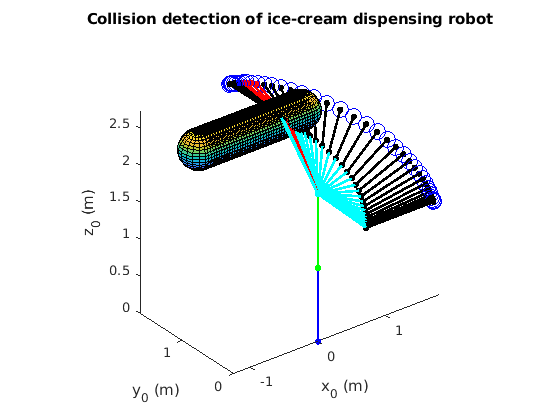

*Figure 10: Demonstrating collision detection across various positions with a moving object*

clear all 
close all

% Link parameters
d1=1; a2=1; a3=1; a4=1; gamma=pi/4;

interval = 20; % Specify number of points in each trajectory

% Specify start and desired joint positions
q = [0 pi/2; % q1_start, q1_desired
    0 0; % q2_start, q2_desired
    0 pi/2]; % q3_start, q3_desired

% Note q4 is calculated below to ensure final link is always parallel to
% ground

segmentsperlink = 3; % Specify how many segments per link for collision checking
t0=0; % Start time (can change to any positive number)
alpha=10; % Max angular acceleration of all joints (deg/s^2)

% Generate trajectory in Traj_mat matrix, where ith row corresponds to ith
% joint
for i=1:length(q)
    q0=q(i,1);
    qf=q(i,2);
    [t,traj]=trajplan(q0,qf,t0,alpha,interval);
    Traj_mat(i,:)=traj; 
end

% Solve for joint 4 trajectory based on geometry:
Traj_mat(4,:)= pi/2 - gamma - Traj_mat(2,:) - Traj_mat(3,:) ;

matlen=length(Traj_mat);
% Specify motion of center of sphere (x,y,z)
pos=[linspace(-1,0.5,matlen); linspace(1,1,matlen);linspace(2.5,2.5,matlen)];
rad=0.25; % Sphere radius


% Run main loop. 
for i=1:length(Traj_mat)
    % Specify DH table. 
    a_vec = [0, a2, a3, a4]; 
    alpha_vec = [pi/2, 0, 0, 0]; 
    d_vec = [d1, 0, 0, 0]; 
    
    % Specify theta from min time trajectory generated earlier.
    theta1=Traj_mat(1,i); theta2=Traj_mat(2,i); theta3=Traj_mat(3,i); theta4=Traj_mat(4,i);
    theta_vec = [theta1, theta2 + pi/2, theta3 - pi/2 - gamma, theta4];
    
    % Compute FK and output H matrix and location of each frame in P_vec:
    [H, P_vec, All_H] = DHmatrix(a_vec,d_vec,alpha_vec,theta_vec); 
    
    % Check if in collision with moving sphere:
    [inCol, index]=check_collision(P_vec,pos(:,i),rad,segmentsperlink);
    
    % Plot the robot links:
    plot_link_collision(P_vec,i,length(Traj_mat),index); 
    
    % Plot the obstacle:
    plot_sphere(pos(:,i),rad)

end
xlabel('x_0 (m)'); ylabel('y_0 (m)'); zlabel('z_0 (m)'); title('Collision detection of ice-cream dispensing robot')

### Functions

#### z_from_transform

Given a transformation, grab the z rotation column and return it as a matrix. This is useful for the Jacobian matrix calculations.

function z = z_from_transform(transform)
    z = transform(1:3, 3);
end

#### translation_from_transform

Given a transformation, isolate the translation column from it. This is useful for the Jacobian matrix calculations.

function o = translation_from_transform(transform)
    o = transform(1:3, 4);
end

#### transformations_from_dh_table

Given a DH table, move through each row and create a series of transformations back to the base (0th frame). This function returns a singular cell of each transformation relative to its frame transformation - where the i-th cell is the $H_i^0$ transformation.

function transforms = transforms_from_dh_table(dh_table, vargin)
    transforms = {};
    transform = 1;
    for row = 1:length(dh_table)
        if nargin == 2
            transforms{end+1} = simplify(transform * transform_from_dh_row(dh_table, row, true));
        else
            transforms{end+1} = transform * transform_from_dh_row(dh_table, row);
        end
        transform = transforms{end};
    end
end

#### jacobian_from_dh

Given a DH table, generate the Jacobian for that DH table. If an additional, second argument is passed if the DH table contains symbolic values, allowing us to do symbolic Jacobian generation instead of a numeric calculation. Extra steps are handled for symbolics - sin vs sind (radians over degrees) and routinely tries to simplify the Jacobian as it is generated.

function j = jacobian_from_dh_table(dh_table, vargin)
    if nargin == 2
        % Initialize our jacobian matrix
        j = sym(zeros(6, length(dh_table)));
        transforms = transforms_from_dh_table(dh_table, true);
    else
        % Initialize our jacobian matrix
        j = zeros(6, length(dh_table));
        transforms = transforms_from_dh_table(dh_table);
    end
    
    o_n = translation_from_transform(transforms{length(dh_table)});
    
    % Prep each row
    for row = 1:length(dh_table)
        row;
        if row == 1
           z_i = [0; 0; 1;];
        else
           transform = transforms{row-1}; 
           z_i = z_from_transform(transform);
        end
        
        if row == 1
           o_i = [0; 0; 0;]; 
        else
           transform = transforms{row-1};
           o_i = translation_from_transform(transform);
        end
        o_i;
        if nargin == 2
            j(1:3, row) = simplify(cross(z_i, o_n-o_i));
        else
            j(1:3, row) = cross(z_i, o_n-o_i);
        end
        cross(z_i, o_n-o_i);
        j(4:6, row) = z_i;
    end
end

#### transform_from_dh_values

This function takes the expected DH values - $\theta$, *d*, *a*, and $\alpha$. It then generates a transform for the given link.

The use of *vargin* is used to determine if an optional parameter is passed. This optional parameter is used to determine if the caller of the function wishes to make use of symbolic values. If so, we use *cos* and *sin* instead of *cosd *and *sind* respectively. This results in slightly better outputs for symbolic functions.

function H = transform_from_dh_values(theta, d, a, alpha, varargin)
    if nargin == 4
        R_z_theta = [ cosd(theta)      -sind(theta)     0     0;
                      sind(theta)       cosd(theta)     0     0;
                      0                 0               1     0;
                      0                 0               0     1; ];
        R_x_alpha = [ 1     0               0            0;
                      0     cosd(alpha)     -sind(alpha) 0;
                      0     sind(alpha)     cosd(alpha)  0;
                      0     0               0            1; ];
    else
        R_z_theta = [ cos(theta)      -sin(theta)     0     0;
                      sin(theta)       cos(theta)     0     0;
                      0                0              1     0;
                      0                0              0     1; ];
        R_x_alpha = [ 1     0              0            0;
                      0     cos(alpha)     -sin(alpha)  0;
                      0     sin(alpha)     cos(alpha)   0;
                      0     0              0            1; ];
    end
    
    
    T_z_d = [ 1     0      0    0;
              0     1      0    0;
              0     0      1    d;
              0     0      0    1; ];
    
    T_x_a = [ 1     0      0    a;
              0     1      0    0;
              0     0      1    0;
              0     0      0    1; ];
    
    
    
    H = R_z_theta * T_z_d * T_x_a * R_x_alpha;
end

#### transform_from_dh_row

This is a helper function that takes a DH table as defined above (in the form of a cell of matricies of expected DH values in a set standard order of $\theta$, *d*, *a*, and $\alpha$. It then separates out the $\theta$, *d*, *a*, and $\alpha$ of the specified row, and passes it to **transform_from_dh_values**, as described above. The use of *vargin* is passed through, for reasons specified above.

function H = transform_from_dh_row(table, row, vargin)
    theta = table{row}(1);
    d = table{row}(2);
    a = table{row}(3);
    alpha = table{row}(4);
    if nargin == 2
        H = transform_from_dh_values(theta, d, a, alpha);
    else
        H = transform_from_dh_values(theta, d, a, alpha, true);
    end
end

#### trajplan

**trajplan** Takes the joint configurations $q_0$ and $q_f$, an initial time $t_0$, an $\alpha$, and a time interval, and generates the trajectory velocity and acceleration profiles.

function [tvec, traj] = trajplan(q0,qf,t0,alpha,interval)
% Computes minimal time trajectory 
    if qf>q0
        ts=sqrt((qf-q0)/alpha);
        t1=linspace(0,ts,interval);
        t2=linspace(ts,2*ts,interval);
        ang_pos1 = 0.5*alpha*t1.^2;
        ang_pos2 = -0.5*alpha*t2.^2 + 2*alpha*ts*t2 - alpha*ts^2;
        tvec=t0+[t1,t2];
        traj=(q0+[ang_pos1,ang_pos2]);
    end
    if q0>qf
        ts=sqrt((q0-qf)/alpha);
        t1=linspace(0,ts,interval);
        t2=linspace(ts,2*ts,interval);
        ang_pos1 = -0.5*alpha*t1.^2;
        ang_pos2 = -(-0.5*alpha*t2.^2 + 2*alpha*ts*t2 - alpha*ts^2);
        tvec=t0+[t1,t2];
        traj=(q0+[ang_pos1,ang_pos2]);
    end
    if q0==qf
        tvec=t0+linspace(0,0,2*interval);
        traj=q0*ones(1,2*interval);
    end
end

#### DHmatrix

**DHmatrix** is a function that calculates the homogeneous transformation matrix H using DH convention input parameters and outputs the final $H_n^0$, the position of all frames ($P_{\textrm{vec}}$), and all the H matrices. 

function [H, P_vec, All_H] = DHmatrix(a_vec,d_vec,alpha_vec,theta_vec)
H=eye(4);
P = [0;0;0;1];
P_vec = zeros(4,length(a_vec));
    for i=1:length(a_vec)
        a=a_vec(i); d=d_vec(i); alpha=alpha_vec(i); theta=theta_vec(i);
        H_tmp = [cos(theta), -sin(theta)*cos(alpha), sin(theta)*sin(alpha), a*cos(theta); ...
        sin(theta), cos(theta)*cos(alpha), -cos(theta)*sin(alpha), a*sin(theta); ...
        0, sin(alpha), cos(alpha), d; ...
        0, 0, 0, 1];
       
        H=H*H_tmp;
        All_H(:,:,i) = H;
        P_vec(1:4,i) = H*P;
    end
end

#### plot_link

**plot_link** is a function that plots each link with input $P_{\textrm{vec}}$ that describes the origin of each frame.

function plot_link(P_vec,current,end_condition)
    A = [0 P_vec(1,:)];
    B = [0 P_vec(2,:)];
    C = [0 P_vec(3,:)];
    h1=plot3(A,B,C,'.-','MarkerSize',12,'LineWidth',2);
    hold on
    h2=plot3(P_vec(1,4),P_vec(2,4),P_vec(3,4),'bo','MarkerSize',12);
    axis equal
    pause(0.05)
    if current~=end_condition && current~=1
        delete(h1)
    end
    
end

#### plot_link_nc

This **plot_link** function does the same, but accepts an end condition as well.


function plot_link_nc(P_vec,current,end_condition)
% This function plots each link with input P_vec that describes the origin
% of each frame.
    A = [0 P_vec(1,:)];
    B = [0 P_vec(2,:)];
    C = [0 P_vec(3,:)];
    
    h1=plot3(A(1:2),B(1:2),C(1:2),'b.-','MarkerSize',12,'LineWidth',2);
    h2=plot3(A(2:3),B(2:3),C(2:3),'g.-','MarkerSize',12,'LineWidth',2);
    h3=plot3(A(3:4),B(3:4),C(3:4),'c.-','MarkerSize',12,'LineWidth',2);
    h4=plot3(A(4:5),B(4:5),C(4:5),'k.-','MarkerSize',12,'LineWidth',2);
    hold on
    h5=plot3(P_vec(1,end),P_vec(2,end),P_vec(3,end),'bo','MarkerSize',12);
    axis equal
    pause(0.1)
    if current~=end_condition
        delete(h1)
        delete(h2)
        delete(h3)
        delete(h4)
    end
    
end

#### look_up_joint_angles

**look_up_joint_angles **takes a given positon of a flavor dispenser (vanilla, chocolate, and mango as your choices), and returns the joint angles to set the end effector to that position.

function Q_mat = look_up_joint_angles(flavor1,flavor2,flavor3)
    vanilla = [0.4, 0.4, 0.4]';  % 1   
    chocolate = [0.6,0.6, 0.6]'; % 2
    mango = [0.8, 0.8,0.8]'; % 3
    flav_sum=flavor1+flavor2+flavor3;
    flav_vec = [flavor1,flavor2,flavor3];
    if flav_sum==0
        Q_mat=NaN;
        return
    end
    count=1;
    for i=1:length(flav_vec)
        if flav_vec(i)==1
            Q_mat(:,count)=vanilla;
            count=count+1;
        end
        if flav_vec(i)==2
            Q_mat(:,count)=chocolate;
            count=count+1;
        end
        if flav_vec(i)==3
            Q_mat(:,count)=mango;
            count=count+1;
        end
    end
end


#### full_traj

Given the points in space that represent key positions - the home position, the cone dispensor, the customer position, and the chosen flavor, generate a set of trajectories that take the robot arm through each position.

function [t_mat, Traj_mat] = full_traj(config_home,config_cone,config_customer,gamma,alpha,interval,n,Q_mat)
    Traj_mat=zeros(4,2*interval,n+3);    
    t_mat = zeros(n+3,2*interval);
    t0=0;
    % Generate trajectory from home to cone dispenser:
    for i=1:3
        q0=config_home(i);
        qf=config_cone(i);
        [t,traj]=trajplan(q0,qf,t0,alpha,interval);
        Traj_mat(i,:,1)=traj; 
    end
    
    Traj_mat(4,:,1)= pi/2 - gamma - Traj_mat(2,:,1) - Traj_mat(3,:,1) ;
    t_mat(1,:)=t;
    
    
    
    % Generate trajectory from cone dispenser to first flavor:
    t0=t_mat(1,end);
    for i=1:3
        q0=config_cone(i);
        qf=Q_mat(i,1);
        [t,traj]=trajplan(q0,qf,t0,alpha,interval);
        Traj_mat(i,:,2)=traj; 
    end
    
    Traj_mat(4,:,2)= pi/2 - gamma - Traj_mat(2,:,2) - Traj_mat(3,:,2) ;
    t_mat(2,:)=t;
    
    
    % Generate trajectory between flavors:
    for j=1:n-1
        t0=t_mat(j+1,end);
        for i=1:3
            q0=Q_mat(i,j);
            qf=Q_mat(i,j+1);
            [t,traj]=trajplan(q0,qf,t0,alpha,interval);
            Traj_mat(i,:,2+j)=traj; 
        end
        Traj_mat(4,:,2+j)= pi/2 - gamma - Traj_mat(2,:,2+j) - Traj_mat(3,:,2+j) ;
        
        t_mat(2+j,:)=t;
        
    end
    
    
    % Generate trajectory from last flavor to customer drop-off:
    t0=t_mat(n+1,end);
    for i=1:3
        q0=Q_mat(i,end);
        qf=config_customer(i);
        [t,traj]=trajplan(q0,qf,t0,alpha,interval);
        Traj_mat(i,:,end-1)=traj; 
    end
    Traj_mat(4,:,end-1)= pi/2 - gamma - Traj_mat(2,:,end-1) - Traj_mat(3,:,end-1) ;
    t_mat(n+2,:)=t;
    
    % Generate trajectory from customer drop-off back to home (last traj):
    t0=t_mat(n+2,end);
    for i=1:3
        q0=config_customer(i);
        qf=config_home(i);
        [t,traj]=trajplan(q0,qf,t0,alpha,interval);
        
        Traj_mat(i,:,end)=traj; 
    end
    Traj_mat(4,:,end)= pi/2 - gamma - Traj_mat(2,:,end) - Traj_mat(3,:,end) ;
    t_mat(n+3,:)=t;
    
end

#### check_collision

**check_collision** will determine whether the robotic arm link encounters a collision with a given obstacle.

function [inCol, index] = check_collision(P_vec,pos,rad,segmentsperlink)
    
    links=length(P_vec);
    inCol=zeros(1,4);
    index=0;
    d=zeros(links,segmentsperlink);
    for i=1:links
        if i==1
            x_pos = linspace(0,P_vec(1,i),segmentsperlink);
            y_pos = linspace(0,P_vec(2,i),segmentsperlink);
            z_pos = linspace(0,P_vec(3,i),segmentsperlink);
            d(1,:) = sqrt((x_pos - pos(1)).^2 + (y_pos - pos(2)).^2 + (z_pos - pos(3)).^2);
        else 
            x_pos = linspace(P_vec(1,i-1),P_vec(1,i),segmentsperlink);
            y_pos = linspace(P_vec(2,i-1),P_vec(2,i),segmentsperlink);
            z_pos = linspace(P_vec(3,i-1),P_vec(3,i),segmentsperlink);
            d(i,:) = sqrt((x_pos - pos(1)).^2 + (y_pos - pos(2)).^2 + (z_pos - pos(3)).^2);
        end
        
    end
    d=transpose(d);
    minperlink = min(d);
    for j=1:links
        if minperlink(j)<rad
            inCol(j)=1;
            index=j;
        end
    end

end

#### plot_link_collision

This **plot_link **function is a modified version of the above **plot_link** function specific for the collision problem above.

function plot_link_collision(P_vec,current,end_condition,index)
% This function plots each link with input P_vec that describes the origin
% of each frame.
    A = [0 P_vec(1,:)];
    B = [0 P_vec(2,:)];
    C = [0 P_vec(3,:)];
    if index==0
        h1=plot3(A(1:2),B(1:2),C(1:2),'b.-','MarkerSize',12,'LineWidth',2);
        h2=plot3(A(2:3),B(2:3),C(2:3),'g.-','MarkerSize',12,'LineWidth',2);
        h3=plot3(A(3:4),B(3:4),C(3:4),'c.-','MarkerSize',12,'LineWidth',2);
        h4=plot3(A(4:5),B(4:5),C(4:5),'k.-','MarkerSize',12,'LineWidth',2);
    else
        h1=plot3(A,B,C,'r.-','MarkerSize',12,'LineWidth',2);
    end
    hold on
    h2=plot3(P_vec(1,end),P_vec(2,end),P_vec(3,end),'bo','MarkerSize',12);
    axis equal
    pause(0.1)    
end

#### plot_sphere

Plot sphere will, given a point in cartesian space, create a sphere of radius of *rad* radians.

function plot_sphere(pos,rad)
    [X,Y,Z] = sphere;
    h1=surf(X*rad+pos(1),Y*rad+pos(2),Z*rad+pos(3));
    pause(0.1)
    hold on
end

## GetDH

Function that calculates HTM using DH parameters (degrees)

This function uses the DH parameter to calculated the HTM using the DH method. This function will work for any number of joints. The output of this function is a cell array

function A = GetDH (a, alpha,d,theta)
    A = {};
    for i = (1:length(a))
    
        H = [ cosd(theta(i)) -sind(theta(i))*cosd(alpha(i)) sind(theta(i))*sind(alpha(i)) a(i)*cosd(theta(i));
            sind(theta(i)) cosd(theta(i))*cosd(alpha(i)) -cosd(theta(i))*sind(alpha(i)) a(i)*sind(theta(i));
            0 sind(alpha(i)) cosd(alpha(i)) d(i);
            0 0 0 1];
        A{i}= simplify((H));
    end
end

#### GetDHrad

Function that calculates HTM using DH parameters (radians).

function A = GetDHrad (a, alpha,d,theta)
    A = {};
    theta = theta*180/pi;
    for i = (1:length(a))
    
        H = [ cosd(theta(i)) -sind(theta(i))*cosd(alpha(i)) sind(theta(i))*sind(alpha(i)) a(i)*cosd(theta(i));
         sind(theta(i)) cosd(theta(i))*cosd(alpha(i)) -cosd(theta(i))*sind(alpha(i)) a(i)*sind(theta(i));
         0 sind(alpha(i)) cosd(alpha(i)) d(i);
         0 0 0 1];
        A{i}= simplify((H));
    end
end

## Discussion

The main objective of this paper was to utilize topics covered in the Foundation of Robotics RBE 500 course at WPI and apply them to an industrial application of robotic arms in the food service industry. To this end, we analyzed an ice-cream serving robot.

### Forward Kinematics

First, we looked at the forward kinematics of the robot. We utilized the DH convention to create a DH table representing the offsets of key frames of the arm. From here we were able to create homogenous transformations of the arm for each joint. Utilizing MATLAB's plotting system, we were able to build and demonstrate a simulation of the robotic arm as it moves. We make use of this information throughout the paper.

### Jacobian and Singularities

When considering methods for covering our robotic arm's Jacobian and then utilizing it to look at singularities, we discovered that the robotic arm, due to its limited degrees of freedom and joint setup, results in a singularity-laden position at all positions. We then demonstrated our analytical and numerical analysis of the arm's Jacobians, and then showed how, through two different methods, the arm was in fact in a singularity.

### Inverse Kinematics

The goal of inverse kinematics is to solve for the required joint angles or configurations needed to achieve a desired postion. For this assignment the inverse kinematics of the problem was calculated using two methods: Numerical and Geometric. The numerical method utilized gradient descent to minimize the error between the desired position and the calculated postion. The geometric method involved first visualizing the robot schematic as a space with overlaping trangles. For this analysis the only known values were the link lengths and the desired position of the end effector. For this method, trigonometric relationships, algebra and triangle rules were used to solve for the angles of the different triangles.

These two methods are very commonly used in robotics. Typically the geometric inverse kinematics method is reserved for simple robotic systems, where the number of degrees of freedom do not surpass 6. The numerical inverse kinematic method is commonly used in industry as it allows for the analysis of complex systems, without requiring much math. For this assignment we calculated the inverse kinematics using both methods in order to compare and contrast the performance and results of both methods. 

The numerical method for solving the inverse kinematics of the system was relatively easy to set up. It involved iteritively calculating for the joint angles and using the uper jacobian to calculate the step with which each sequential configuration was increased by. This method used a threshold error value that will end the iterative calculation once the error falls below the error value. When implementing this method, we found that sometimes the error value asymptotes and doesn't reach the threshold and as a result the computation runs forever. To remedy this, a check was added that breaks the loop if the error starts to asymtote. When looking at the results of this calculation we found that the speed of the calculation varies greatly depending on the the desired position input. We used forward kinematics to check the solution that we obtained. Using forward kinematics allowed us to use the calculated joint values that were calculated to solve for the position that results from the configuration, which should be the desired positon input. When applying this method we found that output position was within the error calculated for the input desired position.

For the geometric approach, the robot was divided into four overlapping triangles. Each triangle was analyzed and the components of these triangles were then solved from using trigonometry and geometry. This method was harder than the numerical analysis to setup, as it involved more math and analysis, but it was computationally faster. This is because this method does not involve iterations and has a finite number of calculations. When implementing this method, we used forward kinematics to check the answer that we obtained usining inverse kinematics. When applying and checking this method, we found that the results were what we were expecting. The position desired inputted in the forward kinematics matched inthe output of the forward kinematics. 

When contrasting the two methods, we found that numerical method was easier to implement but slower to execute. The geometric method was more difficult to setup as it involved more math, but faster to execute. Both geometric and numerical approaches to IK are widely used; however numerical is more commonly used in industry. For the application of this project, due to the symplicity of the system (it only has four degrees of freedom), using geometric approach is perfectly acceptable and more accurate. 

### Trajectory Planning

Here we implemented minimal time trajectory for all 4 joints of the ice cream dispensing robot based on user preference of any combination of 3 flavors. In particular, the trajectory implemented are minimal time (under the constraint of 0 velocity at each desired configuration) and we also imposed a constraint on the last link of the robot to ensure it is always parallel to the ground so that the ice-cream cone does not tip over. 

While minimal time trajectory generation is computationally efficient and results in the fastest cycle time, it is impractical to instantaneously have maximum joint acceleration and then switch to maximum joint deceleration. 

### **Collision Detection**

We also performed collision detection for all 4 links of the manipulator and a moving spherical obstacle. This was accomplished by segmenting the link into smaller line segments and checking the distance between each segment to the center of the obstacle. If any segment was within a certain distance to the obstacle center, we displayed this condition by coloring all links red. 

Though not a sophisticated result, this is practically useful since there will always be a need to ensure the manipulator does not collide with any objects/human within its workspace. A more sophisticated system would perhaps use a vision system to track the motion of multiple obstacles and convert these to positions relative to the manipulator. 

## Citations

**[1] ***A. Sharma, P. Zanotti and L. P. Musunur, "Drive Through Robotics: Robotic Automation for Last Mile Distribution of Food and Essentials During Pandemics," in IEEE Access, vol. 8, pp. 127190-127219, 2020, doi: 10.1109/ACCESS.2020.3007064.*

**[2]*** A. Rai, C. Chaturvedi, P. K. Maduri and K. Singh, "Autonomous Disinfection Robot," 2020 2nd International Conference on Advances in Computing, Communication Control and Networking (ICACCCN), Greater Noida, India, 2020, pp. 990-996, doi: 10.1109/ICACCCN51052.2020.9362728.*

**[3]*** Z. Xue, S. Ruehl, A. Hermann, T. Kerscher and R. Dillmann, "An autonomous ice-cream serving robot," 2011 IEEE International Conference on Robotics and Automation, Shanghai, China, 2011, pp. 3451-3452, doi: 10.1109/ICRA.2011.5980335.*

**[4] ***P. Long, W. Khalil and P. Martinet, "Modeling & control of a meat-cutting robotic cell," 2013 16th International Conference on Advanced Robotics (ICAR), Montevideo, Uruguay, 2013, pp. 1-6, doi: 10.1109/ICAR.2013.6766471.*

**[5]** *R. J. Moreno Masey and D. G. Caldwell, "Design of an Automated Handling System for Limp, Flexible Sheet Lasagna Pasta," Proceedings 2007 IEEE International Conference on Robotics and Automation, Rome, Italy, 2007, pp. 1226-1231, doi: 10.1109/ROBOT.2007.363152.*

**[6]***  D. A. Drexler, "Solution of the closed-loop inverse kinematics algorithm using the Crank-Nicolson method," 2016 IEEE 14th International Symposium on Applied Machine Intelligence and Informatics (SAMI), Herlany, Slovakia, 2016, pp. 351-356, doi: 10.1109/SAMI.2016.7423033.*